# Neuroscience Example: Quantal Release

Exercises were done with the help of ChatGPT; here is a link to the conversation: 

[https://chat.openai.com/share/9fce01ae-fdcb-4b45-9387-a7cad555abaf](https://chat.openai.com/share/9fce01ae-fdcb-4b45-9387-a7cad555abaf) 

From: Johnson, E.W., and Wernig, A. (1971). [The binomial nature of transmitter release at the crayfish neuromuscular junction](https://colab.research.google.com/corgiredirector?site=https%3A%2F%2Fwww.ncbi.nlm.nih.gov%2Fpmc%2Farticles%2FPMC1331610%2F). J Physiol 218, 757-767.

Classic studies by [Bernard Katz and colleagues](https://colab.research.google.com/corgiredirector?site=https%3A%2F%2Fwww.ncbi.nlm.nih.gov%2Fpmc%2Farticles%2FPMC2151334%2F) indicated that chemical neurotransmitters are released from presynaptic nerve terminals in discrete quanta, or packets, with a relatively constant release probability. A straightforward implication of this idea is that the release statistics (i.e., the distribution of the number of quanta that are actually released in response to a given event like an action potential reaching the presynaptic nerve terminal) should follow a binomial distribution. As stated by Johnson and Wernig:

"If the average probability of release is constant, then it follows from the hypothesis that the relative frequency of 0, 1, 2, 3, . . . quantal releases in a series of trials is given by the successive terms in the binomial expansion (𝑝+𝑞)𝑛, where *q*=1–*p* is the average probability that a quantum will not be released. In a given trial, the probability that *x* quanta will be released (*px*) is given by the binomial term" [i.e., Eq. 1, above, but substitute *x* for *k*].

In other words, if there are *n* available quanta in a presynaptic terminal, and each is released with probability *p*, then the number of quanta that are actually released should follow a binomial distribution with parameters *n* and *p*.

Answers to the exercises below will be found [here](https://github.com/PennNGG/Quantitative-Neuroscience/tree/master/Answers%20to%20Exercises/Python) after the due date.

## Exercise 1

Assume that there are 10 quanta available in a nerve terminal, and for a given release event each is released with a probability of 0.2. For one such event, what is the probability that 0, 1, 2, 3, 4, 5, 6, 7, 8, 9, or 10 quanta will be released?

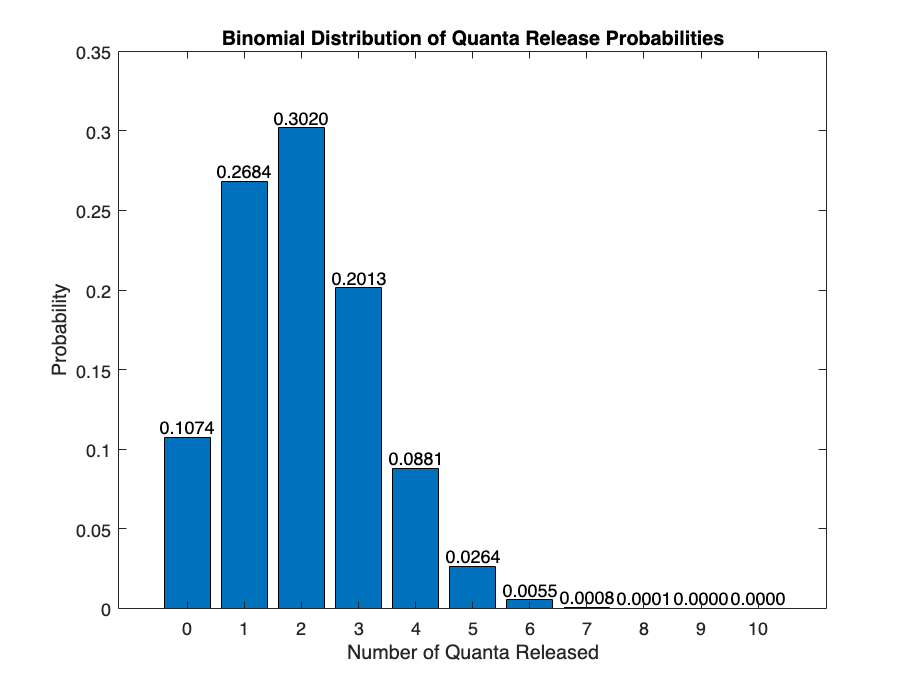

% Define parameters
num_quanta = 10;  % Total number of quanta
release_prob = 0.2;  % Probability of release for each quanta
num_events = 1;  % Number of events

% Generate a vector of possible outcomes (0 to num_quanta)
outcomes = 0:num_quanta;

% Calculate probabilities using binomial distribution formula
probabilities = binopdf(outcomes, num_quanta, release_prob);

% Create a bar graph
bar(outcomes, probabilities);

% Add labels and title
xlabel('Number of Quanta Released');
ylabel('Probability');
title('Binomial Distribution of Quanta Release Probabilities');

% Add probability values on top of bars
for i = 1:length(outcomes)
    text(outcomes(i), probabilities(i), sprintf('%.4f', probabilities(i)), ...
        'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end


## Exercise 2

Let's say you know that a given nerve terminal contains exactly 14 quanta available for release. You have read in the literature that the release probability of these quanta is low, say 0.1. To assess whether this value is reasonable, you run a simple experiment: activate the nerve and measure the number of quanta that are released. The result is 8 quanta. What is the probability that you would get this result (8 quanta) if the true probability of release really was 0.1? What about if the true release probability was much higher; say, 0.7? What about for each decile of release probability (0.1, 0.2, ... 1.0)? Which value of release probability did you determine to be the most probable, given your measurement?

Note: here you are computing a likelihood function: a function describing how the value of the conditional probability *p*(*data* | *parameters*) changes when you hold your data fixed to the value(s) you measured and vary the value(s) of the parameter(s) of, in this case, the binomial distribution. Because you are varying the parameters and not the data, the values of the function are not expected to sum to one (e.g., you can have numerous parameters that have a very high probability of producing the given data) and thus this function is not a probability distribution (see [here](https://colab.research.google.com/corgiredirector?site=https%3A%2F%2Fwww.psychologicalscience.org%2Fobserver%2Fbayes-for-beginners-probability-and-likelihood) for an extended discussion). The maximum value of this function is called the maximum likelihood.

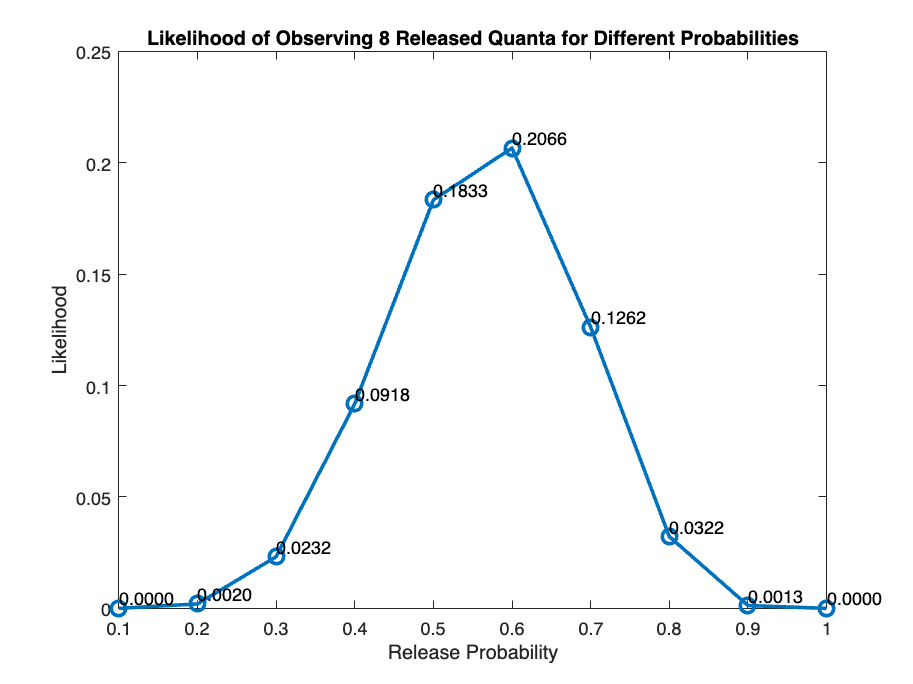

% Define parameters
num_quanta = 14;  % Total number of quanta
observed_quanta = 8;  % Number of observed quanta

% Define the range of release probabilities (from 0.1 to 1.0)
release_probabilities = 0.1:0.1:1.0;

% Initialize arrays to store likelihoods and corresponding probabilities
likelihoods = zeros(size(release_probabilities));

% Calculate likelihood for each release probability
for i = 1:length(release_probabilities)
    release_prob = release_probabilities(i);
    likelihoods(i) = binopdf(observed_quanta, num_quanta, release_prob);
end

% Create a line plot
plot(release_probabilities, likelihoods, 'o-', 'MarkerSize', 8, 'LineWidth', 2);

% Add labels and title
xlabel('Release Probability');
ylabel('Likelihood');
title('Likelihood of Observing 8 Released Quanta for Different Probabilities');

% Add likelihood values next to the corresponding points
for i = 1:length(release_probabilities)
    text(release_probabilities(i), likelihoods(i), sprintf('%.4f', likelihoods(i)), ...
        'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');
end

## Exercise 3

Not feeling convinced by your single experiment (good scientist!), you repeat it under identical conditions. This time you measure 5 quanta that were released. Your sample size has now doubled, to two measurements. You now want to take into account both measurements when you assess the likelihoods of different possible values of the underlying release probability. To do so, assume that the two measurements in this sample are independent of one another; that is, the value of each result had no bearing on the other. In this case, the total likelihood is simply the product of the likelihoods associated with each separate measurement. It is also typical to compute the logarithm of each likelihood and take their sum, which is often more convenient. What are the values of the total likelihood and total log-likelihood in this example, if we assume that the true release probability is 0.1?

Of course, knowing those values of the likelihood and log-likelihood is not particularly useful until you can compare them to the values computed for other possible values for the release probability, so you can determine which value of release probability is most likely, given the data. Therefore, compute the full likelihood and log-likelihood functions using deciles of release probability between 0 and 1. What is the maximum value? Can you improve your estimate by computing the functions at a higher resolution? How does the estimate improve as you increase the sample size?

% Define parameters
num_quanta = 14;  % Total number of quanta

% Define observed outcomes
observed_outcomes = [8, 5];

% Define true release probability
p = 0.1;

% Calculate likelihoods for both experiments
likelihood_1 = binopdf(observed_outcomes(1), num_quanta, p);
likelihood_2 = binopdf(observed_outcomes(2), num_quanta, p);

% Calculate total likelihood and total log-likelihood
total_likelihood = likelihood_1 * likelihood_2;
total_log_likelihood = log(likelihood_1) + log(likelihood_2);

disp(['Total Likelihood: ', num2str(total_likelihood)]);

Total Likelihood: 1.2378e-07


disp(['Total Log-Likelihood: ', num2str(total_log_likelihood)]);

Total Log-Likelihood: -15.9047


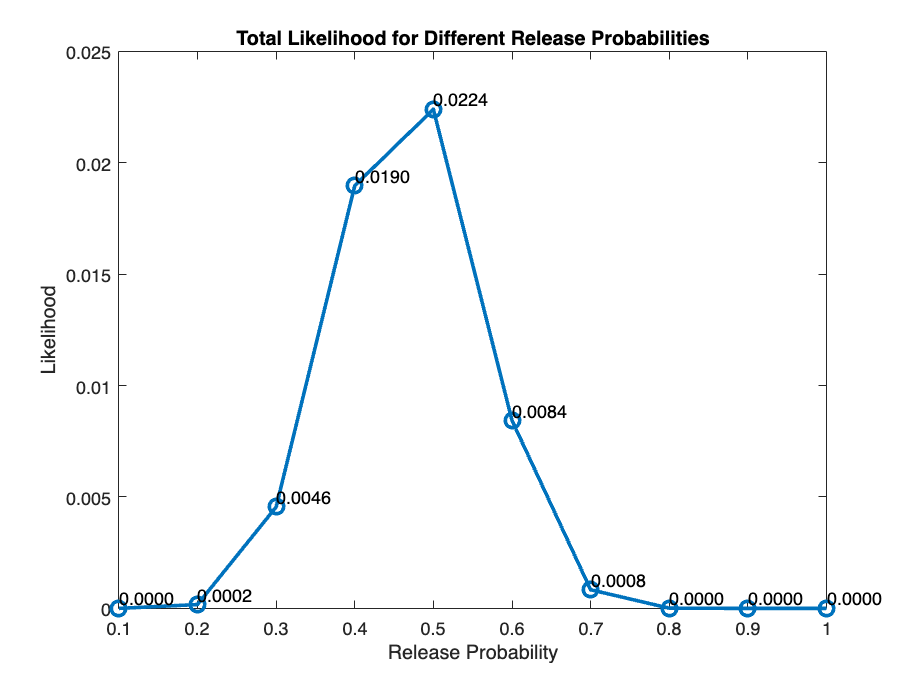

% Define the range of release probabilities (from 0.1 to 1.0)
release_probabilities = 0.1:0.1:1.0;

% Initialize arrays to store likelihoods and log-likelihoods
likelihoods = zeros(size(release_probabilities));
log_likelihoods = zeros(size(release_probabilities));

% Calculate likelihoods and log-likelihoods for each release probability
for i = 1:length(release_probabilities)
    p = release_probabilities(i);
    likelihoods(i) = binopdf(observed_outcomes(1), num_quanta, p) * binopdf(observed_outcomes(2), num_quanta, p);
    log_likelihoods(i) = log(binopdf(observed_outcomes(1), num_quanta, p)) + log(binopdf(observed_outcomes(2), num_quanta, p));
end

% Find the maximum likelihood and corresponding release probability
[max_likelihood, max_likelihood_idx] = max(likelihoods);
max_likelihood_prob = release_probabilities(max_likelihood_idx);

% Find the maximum log-likelihood and corresponding release probability
[max_log_likelihood, max_log_likelihood_idx] = max(log_likelihoods);
max_log_likelihood_prob = release_probabilities(max_log_likelihood_idx);

% Create a line plot for likelihoods
figure;
plot(release_probabilities, likelihoods, 'o-', 'MarkerSize', 8, 'LineWidth', 2);
xlabel('Release Probability');
ylabel('Likelihood');
title('Total Likelihood for Different Release Probabilities');

% Add likelihood values next to the corresponding points
for i = 1:length(release_probabilities)
    text(release_probabilities(i), likelihoods(i), sprintf('%.4f', likelihoods(i)), ...
        'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');
end

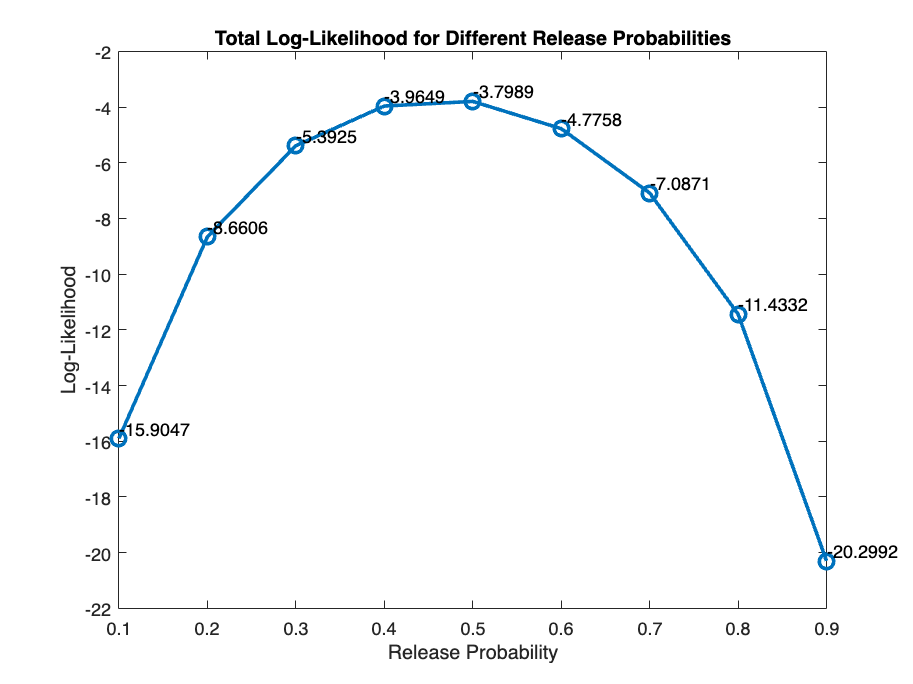


% Create a line plot for log-likelihoods
figure;
plot(release_probabilities, log_likelihoods, 'o-', 'MarkerSize', 8, 'LineWidth', 2);
xlabel('Release Probability');
ylabel('Log-Likelihood');
title('Total Log-Likelihood for Different Release Probabilities');

% Add log-likelihood values next to the corresponding points
for i = 1:length(release_probabilities)
    text(release_probabilities(i), log_likelihoods(i), sprintf('%.4f', log_likelihoods(i)), ...
        'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');
end


disp(['Maximum Likelihood: ', num2str(max_likelihood)]);

Maximum Likelihood: 0.022396


disp(['Corresponding Release Probability: ', num2str(max_likelihood_prob)]);

Corresponding Release Probability: 0.5


disp(['Maximum Log-Likelihood: ', num2str(max_log_likelihood)]);

Maximum Log-Likelihood: -3.7989


disp(['Corresponding Release Probability: ', num2str(max_log_likelihood_prob)]);

Corresponding Release Probability: 0.5


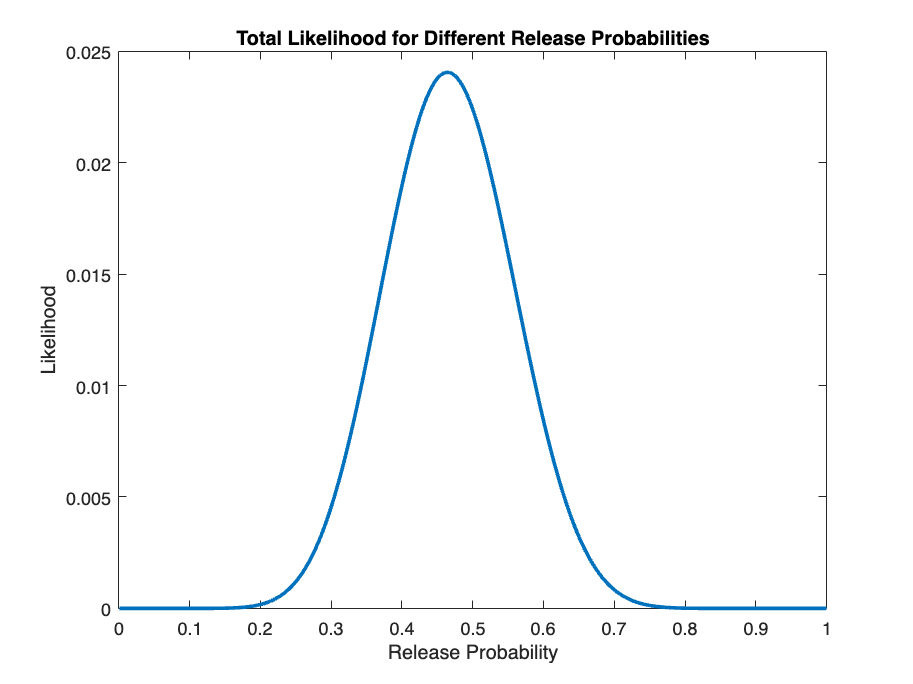

% Define the range of release probabilities (from 0.001 to 1.0)
release_probabilities = 0.001:0.001:1.0;

% Initialize arrays to store likelihoods and log-likelihoods
likelihoods = zeros(size(release_probabilities));
log_likelihoods = zeros(size(release_probabilities));

% Calculate likelihoods and log-likelihoods for each release probability
for i = 1:length(release_probabilities)
    p = release_probabilities(i);
    likelihoods(i) = binopdf(observed_outcomes(1), num_quanta, p) * binopdf(observed_outcomes(2), num_quanta, p);
    log_likelihoods(i) = log(binopdf(observed_outcomes(1), num_quanta, p)) + log(binopdf(observed_outcomes(2), num_quanta, p));
end

% Find the maximum likelihood and corresponding release probability
[max_likelihood, max_likelihood_idx] = max(likelihoods);
max_likelihood_prob = release_probabilities(max_likelihood_idx);

% Find the maximum log-likelihood and corresponding release probability
[max_log_likelihood, max_log_likelihood_idx] = max(log_likelihoods);
max_log_likelihood_prob = release_probabilities(max_log_likelihood_idx);

% Create a line plot for likelihoods
figure;
plot(release_probabilities, likelihoods, 'LineWidth', 2);
xlabel('Release Probability');
ylabel('Likelihood');
title('Total Likelihood for Different Release Probabilities');

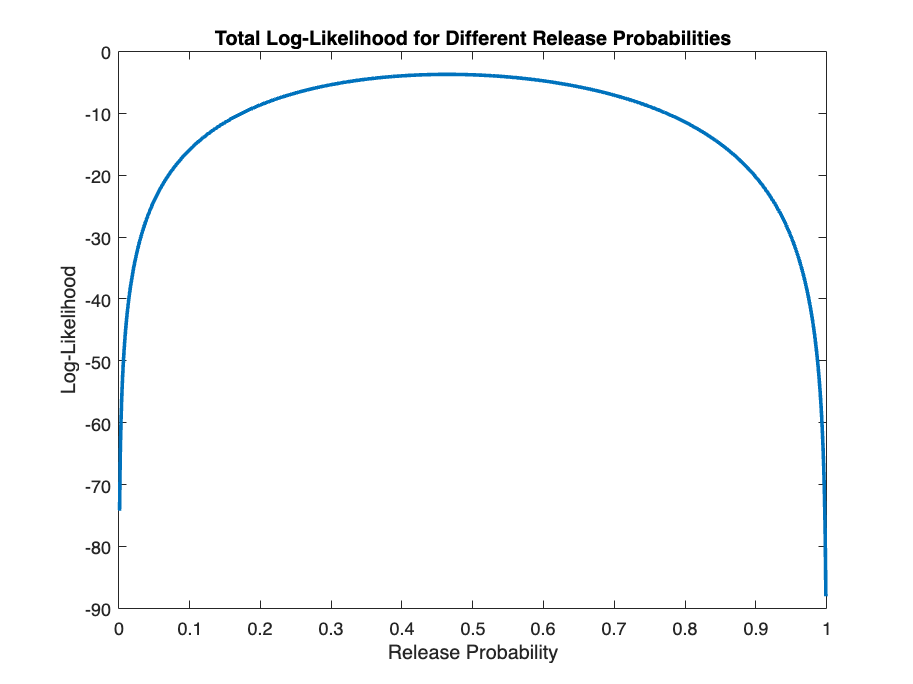


% Create a line plot for log-likelihoods
figure;
plot(release_probabilities, log_likelihoods, 'LineWidth', 2);
xlabel('Release Probability');
ylabel('Log-Likelihood');
title('Total Log-Likelihood for Different Release Probabilities');


disp(['Maximum Likelihood: ', num2str(max_likelihood)]);

Maximum Likelihood: 0.024056


disp(['Corresponding Release Probability: ', num2str(max_likelihood_prob)]);

Corresponding Release Probability: 0.464


disp(['Maximum Log-Likelihood: ', num2str(max_log_likelihood)]);

Maximum Log-Likelihood: -3.7274


Corresponding Release Probability: 0.464


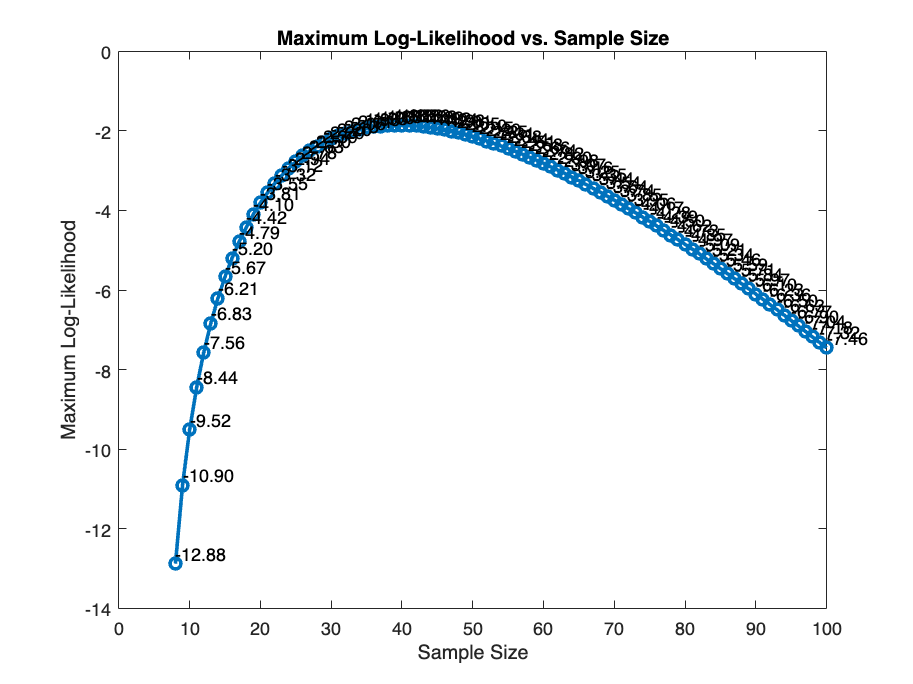

disp(['Corresponding Release Probability: ', num2str(max_log_likelihood_prob)]);

## Exercise 4

You keep going and conduct 100 separate experiments and end up with these results:

**Measured releases****Count**

0) 0

1) 0

2 )3

4) 10

5) 19

6) 26

7) 16

8) 16

9) 5

10) 5

11) 0

12) 0

13) 0

14) 0

What is the most likely value of *p* (which we typically refer to as 𝑝̂ , which is pronounced as "p-hat" and represents the maximum-likelihood estimate of a parameter in the population given our sample with a resolution of 0.01?

BONUS: Use a fitting procedure to find 𝑝̂ .

% Define the observed data
observed_data = [
    0,0; 1,0; 2,3; 4,10; 5,19; 6,26; 7,16; 8,16; 9,5; 10,5; 11,0; 12,0; 13,0; 14,0
];

% Calculate the observed proportions
observed_proportions = observed_data(:, 2) ./ observed_data(:, 1);

% Define the range of possible p-hat values (from 0 to 1 with a resolution of 0.01)
phat_values = 0:0.01:1;

% Initialize an array to store likelihoods
likelihoods = zeros(size(phat_values));

% Calculate the likelihood for each p-hat value
for i = 1:length(phat_values)
    phat = phat_values(i);
    likelihoods(i) = prod(binopdf(observed_data(:, 1), 14, phat));
end

% Find the p-hat value that maximizes the likelihood
[max_likelihood, max_likelihood_idx] = max(likelihoods);
max_likelihood_phat = phat_values(max_likelihood_idx);

disp(['Most likely p-hat (Maximum Likelihood Estimate): ', num2str(max_likelihood_phat)]);

Most likely p-hat (Maximum Likelihood Estimate): 0.52


## Exercise 5

Let's say that you have run an exhaustive set of experiments on this synapse and have determined that the true release probability is 0.3 (within some very small tolerance). Now you want to test whether changing the temperature of the preparation affects the release probability. So you change the temperature, perform the experiment, and measure 7 quantal events for the same 14 available quanta. Compute 𝑝̂ . Standard statistical inference now asks the question, what is the probability that you would have obtained that measurement given a Null Hypothesis of no effect? In this case, no effect corresponds to an unchanged value of the true release probability (i.e., its value remained at 0.3 even with the temperature change). What is the probability that you would have gotten that measurement if your Null Hypothesis were true? Can you conclude that temperature had an effect?

% Define parameters
true_p = 0.3;  % True release probability under null hypothesis
observed_outcome = 7;  % Number of quanta released

% Sample size (total number of quanta available for release)
n = 14;

% Calculate p-hat (sample proportion)
phat = observed_outcome / n;

% Calculate standard error for the sample proportion
SE = sqrt(phat*(1-phat)/n);

% Calculate z-score
z = (phat - true_p) / SE;

% Calculate p-value
p_value = 2 * (1 - normcdf(abs(z)));  % Two-tailed test

% Set significance level (alpha)
alpha = 0.05;

% Compare p-value to significance level
if p_value < alpha
    conclusion = 'Reject null hypothesis';
else
    conclusion = 'Fail to reject null hypothesis';
end

disp(['p-hat (sample proportion): ', num2str(phat)]);

p-hat (sample proportion): 0.5


disp(['z-score: ', num2str(z)]);

z-score: 1.4967


disp(['p-value: ', num2str(p_value)]);

p-value: 0.13448


disp(['Conclusion: ', conclusion]);

Conclusion: Fail to reject null hypothesis


## Bonus Exercise

These data are reproduced from Tables 1 and 2 of Johnson and Wernig. Note that *nx* indicates the number of trials ("release events") with *x* measured events. Each row is a separate experiment (don't worry about the ordering, which here is reproduced as it is in the paper).

**Temp (°C)****n0****n1****n2****n3****n4****n5+**

4.061520633200

3.5604339941120

0.033212621100

2.05734431542820

6.5172176891210

3.0802242003240

You can probably already see that some experiments resulted in primarily zero or one events per trial (e.g., the top experiment), whereas others tended to have more events (e.g., the bottom experiment).

Do the quantal event numbers follow a binomial distribution? If so, then that would lend support to the idea that the events are generated by a process that can be characterized in terms of the number of available quanta and the average probability of release of each quantum.

Provide a qualitative answer to this question by comparing the empirical distributions (see the data table, above) to the predicted binomial distribution. To get the predicted distribution (i.e., the probabilities associated with each value of *k* from Eq. 1, given the release probability p and the number of available quanta *n*), you need to determine both *k* and *n* from the empirical measurements. To determine *p*, use Eq. 5 in the paper: 𝑝=1−𝜎2𝑚

where 𝜎2 is the variance and *m* is the mean of the trial-by-trial counts that can be determined from the data. To determine *n*, compute *m*/*p* (because *m* = *n* x *p*).

As an added bonus, also include the predicted Poisson distribution, which can be computed using only the mean number of events (*m*, described above).

# Additional Resources

Working with the binomial distribution in [Matlab](https://colab.research.google.com/corgiredirector?site=https%3A%2F%2Fwww.mathworks.com%2Fhelp%2Fstats%2Fbinomial-distribution.html), [R](https://colab.research.google.com/corgiredirector?site=https%3A%2F%2Fwww.rdocumentation.org%2Fpackages%2Fstats%2Fversions%2F3.3%2Ftopics%2FBinomial), and [Python](https://colab.research.google.com/corgiredirector?site=https%3A%2F%2Fdocs.scipy.org%2Fdoc%2Fscipy%2Freference%2Fgenerated%2Fscipy.stats.binom.html).

# Credits

Copyright 2021 by Joshua I. Gold, University of Pennsylvania